## Initialization

set_path
clc
clear
close all

## Set CPG Feedforward percent

global cpg_percent;
cpg_percent = 0.33;

## Set obj function

global w1;
global w2;
global w3;
global w4;
global w5;
global target_mean_velocity;
global target_height;
global target_frequency;
global target_step_length;

%% change the weight of different analytical parameters to 
% optimize for different targets .
% e.g. only limit w4 to reach higher frequency
w1 = 0; % weight for target velocity
w2 = 3; % weight for CoT
w3 = 5; % weight for target hip height
w4 = 0; % weight for target step frequency
w5 = 0; % weight for target step length

target_mean_velocity = 0;
target_height = 0.5; 
target_frequency = 0; 
target_step_length = 0;

## Set disturbance

### Set internal disturbance here

global sigma;
sigma = 0; %set variance of Gaussian noise internal disturbance

global internal_noise_flag; %set different values for flag here 
internal_noise_flag = 0;
% to change to which the internal noise is applied to
% flag = 0 means no internal noise. flag = 1~3 applies noise to q1~q3. flag
% 4~6 applies noise to dq1~dq3

### Set external disturbace here

global external_force;
external_force = -40; %%set external_force positive to push robot
% forward, negative to pull backward, 0 to disable
% The unit is in Newton and the force acts on the robot hip
% beginning on 4th step and lasts for 2 steps

## Run without optimization

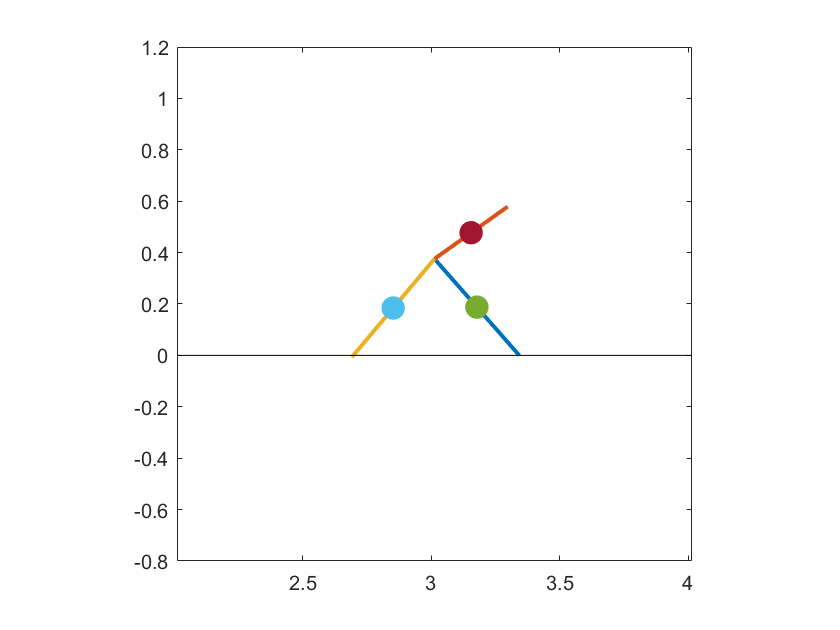

Real time factor:    0.3636



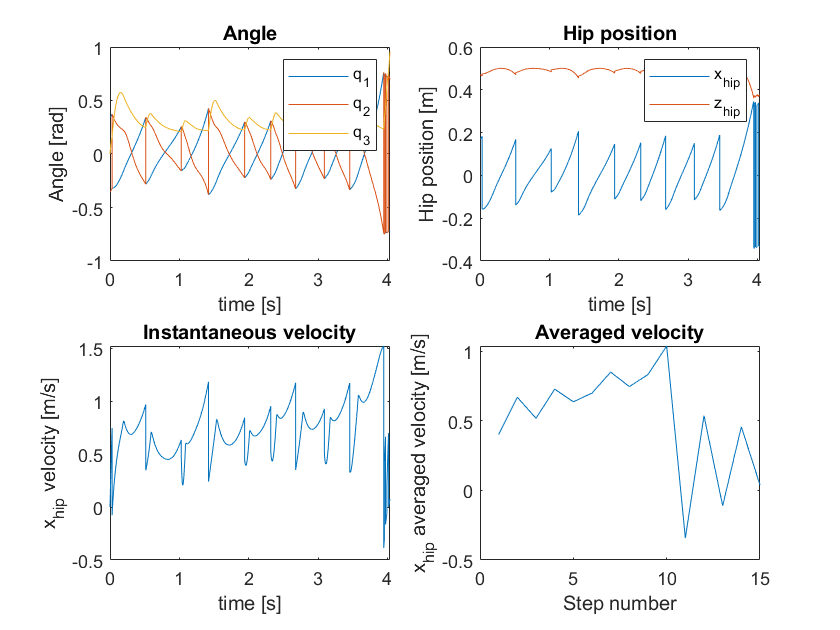

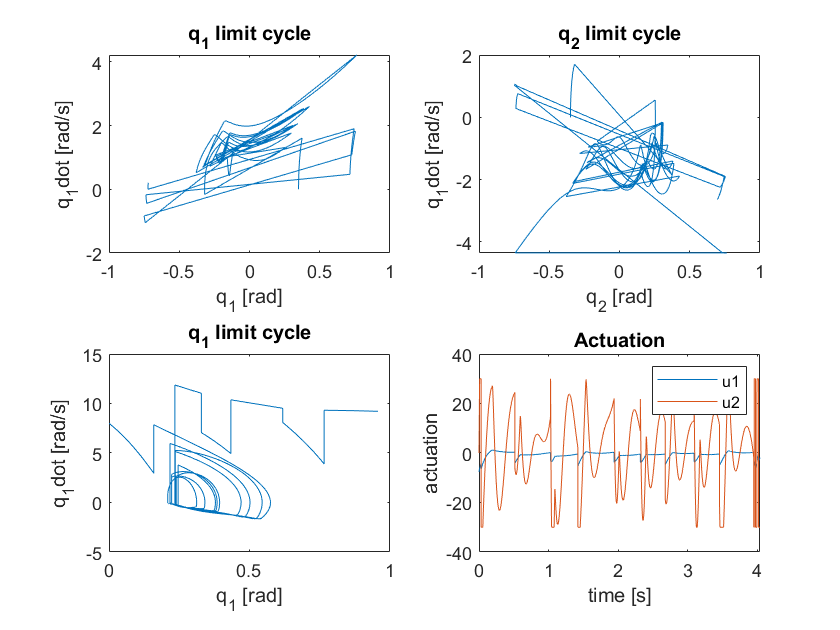

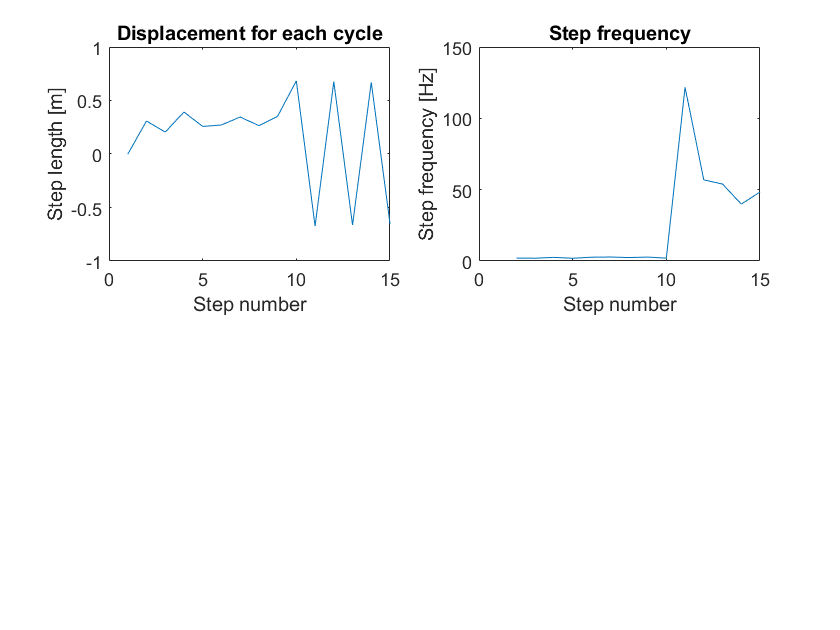

run_simulation

## Run with optimization

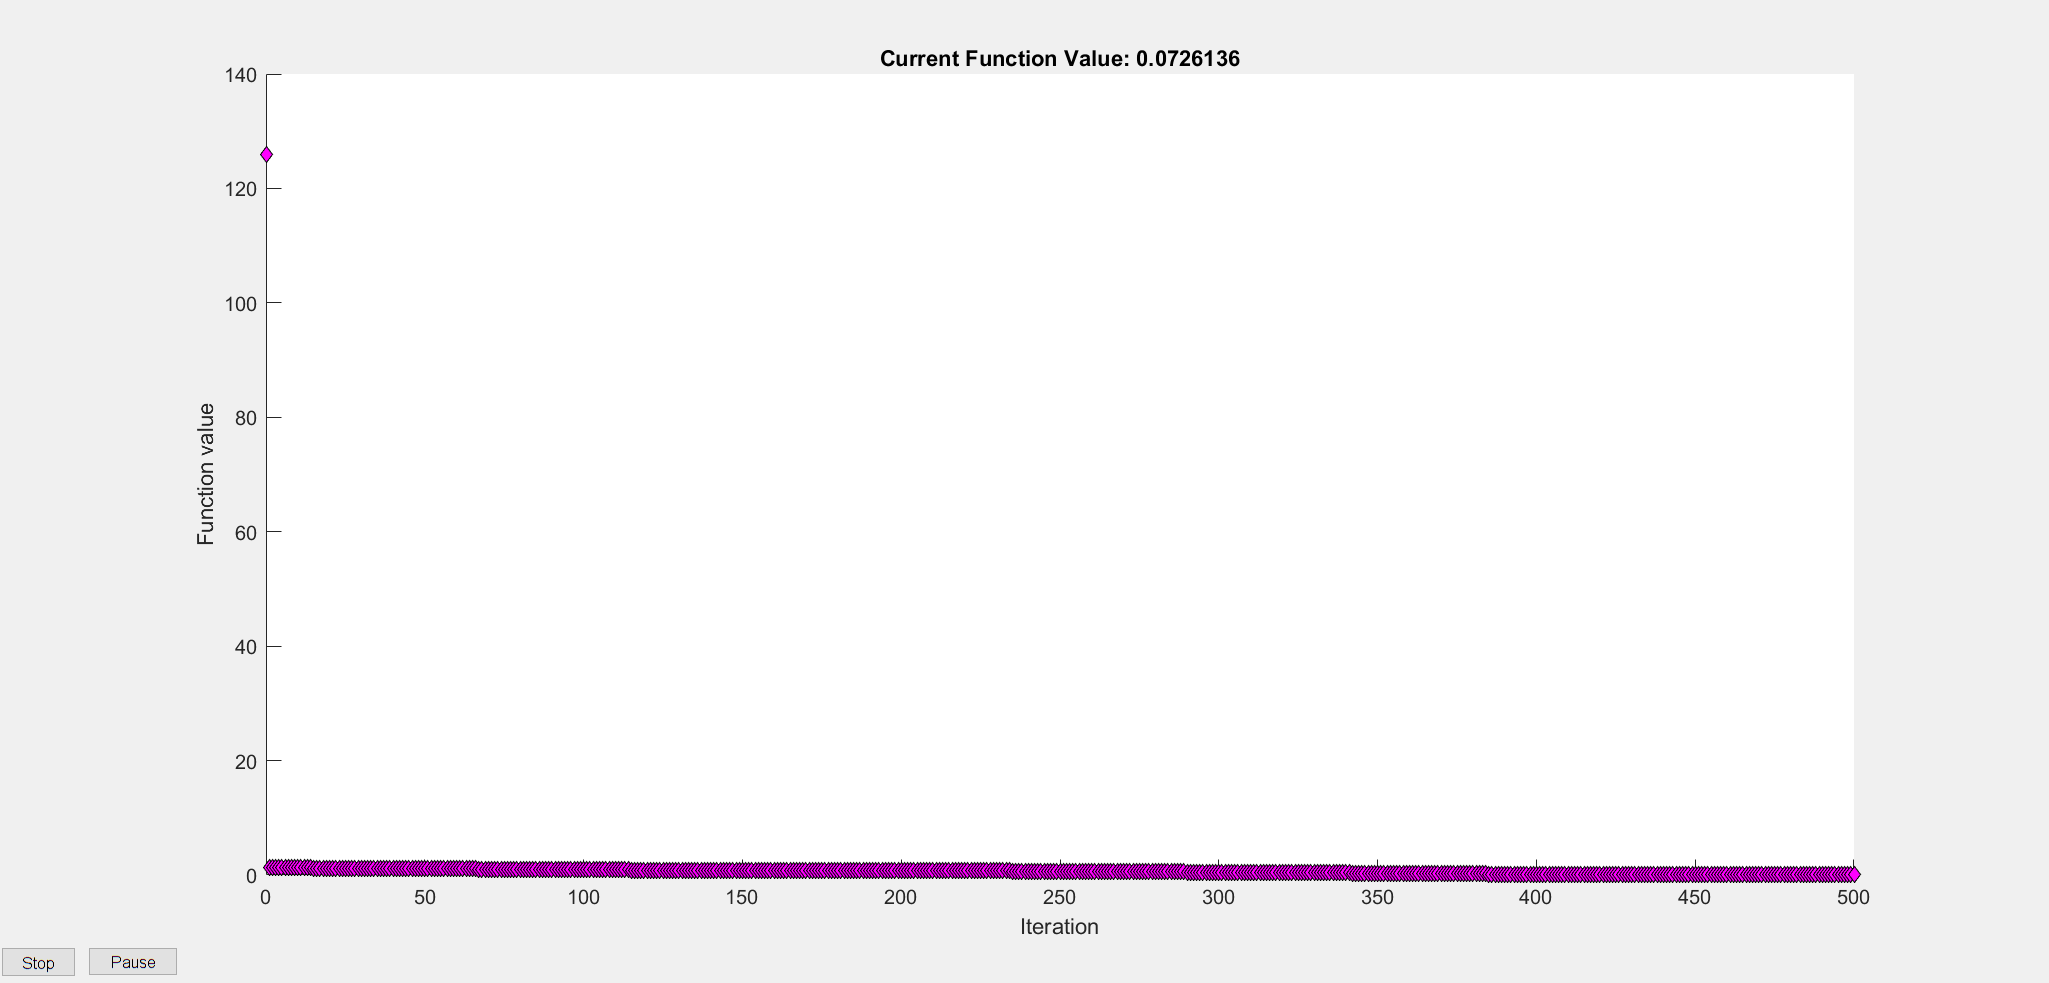

 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 0.072614 



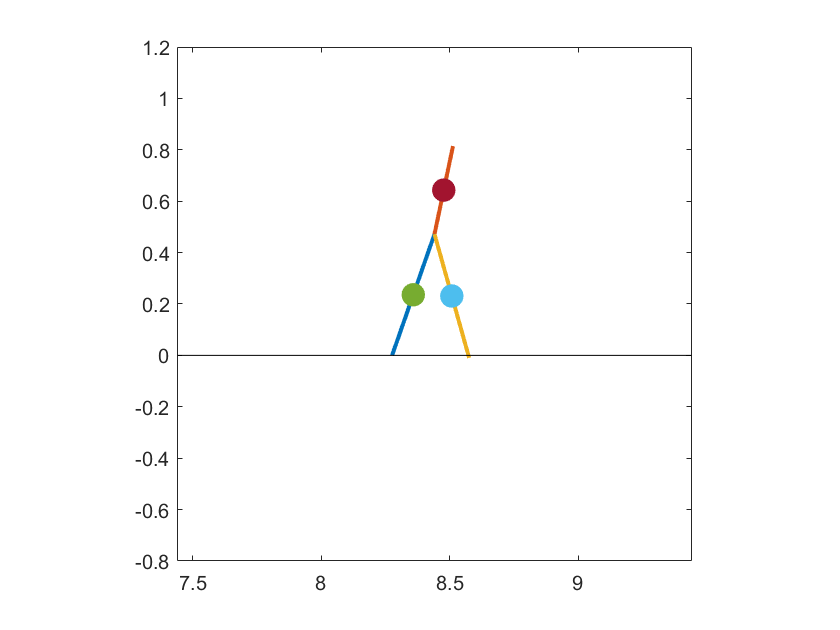

Real time factor:    0.3520



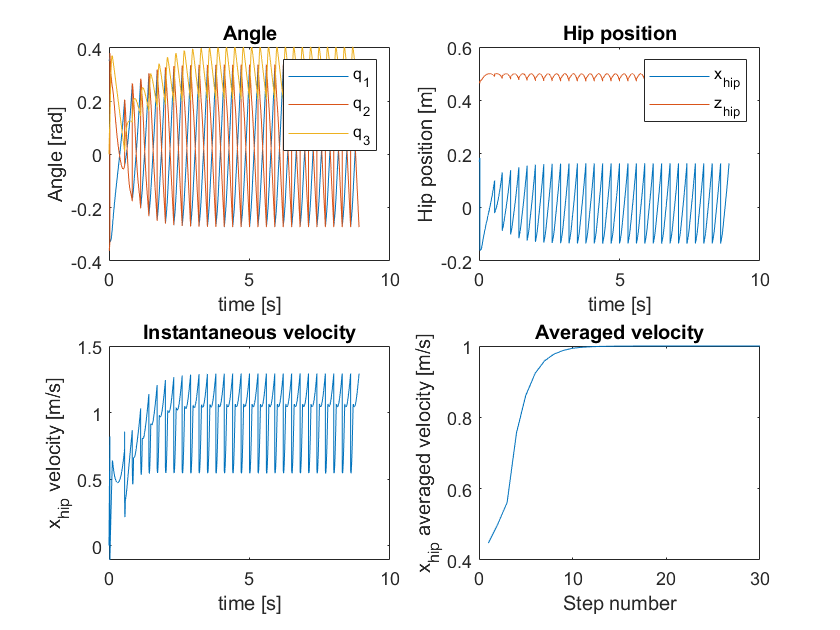

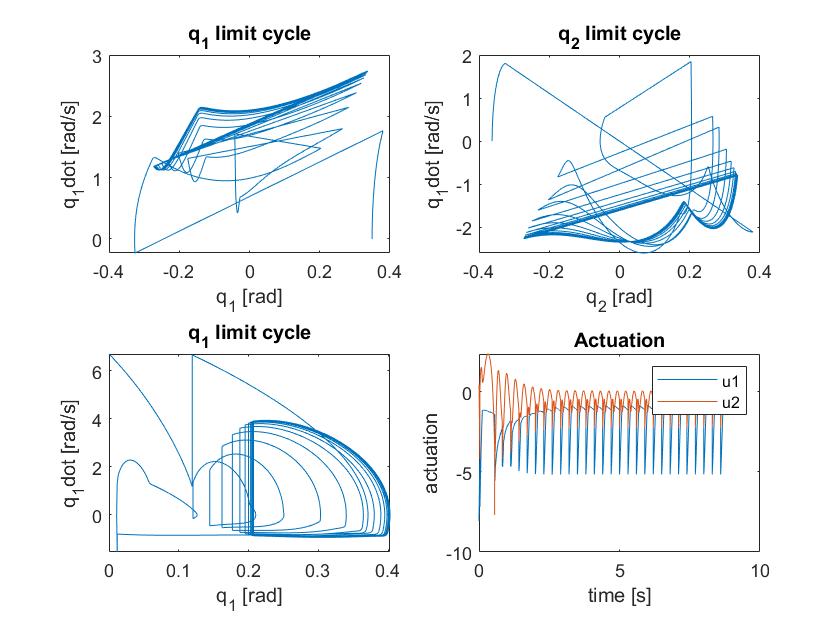

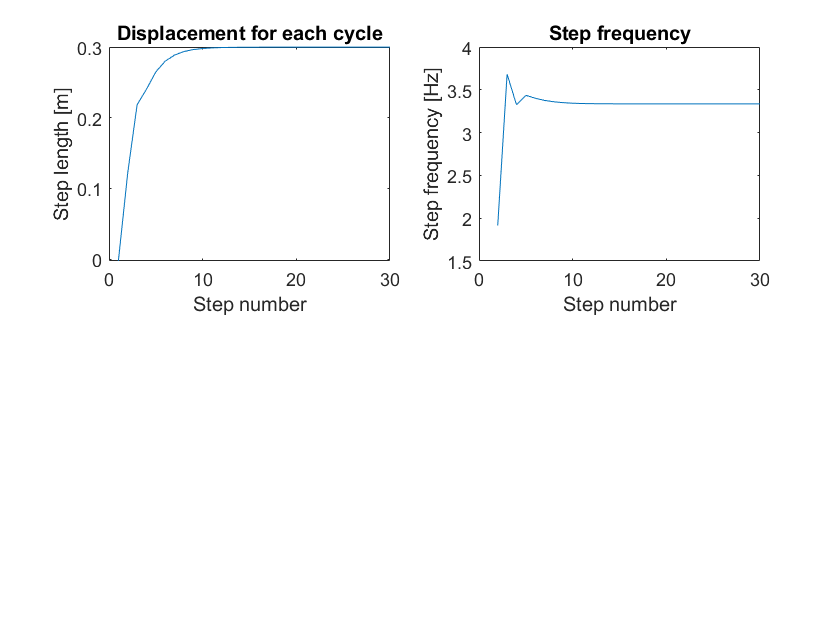

run_optimization %compare the results before and after the optimization and have fun